This is a workboook to attempt to find a mixed effects model for the pilot data collected from Qualtrics for the EEE study. 

By Ben Graul

load('C:\Users\bgrau\GitHub\ieeg_affect\EEE\qualtrics\data\pilot_master_long.mat')
% Use if loading script from GitHub
fname = matlab.desktop.editor.getActiveFilename();
fdir = fileparts(fname);
cd(fdir);
% cd ..\data
% load('pilot_master_long.mat')

What do the data look like? We care about the rating that participants gave to an image after seeing a cue type. 

hicue_val = (master.img_rate(master.highcue_indx == 1));
locue_val = (master.img_rate(master.highcue_indx == -1));

highmean = mean(hicue_val)

highmean = 54.8393

lowmean = mean(locue_val)

lowmean = 50.6549

[h,p,ci,stats] = ttest(hicue_val, locue_val)

h = 1

p = 6.8903e-10

ci =     2.8578
    5.5111


stats = struct with fields:
    tstat: 6.1839
       df: 3935
       sd: 42.4524


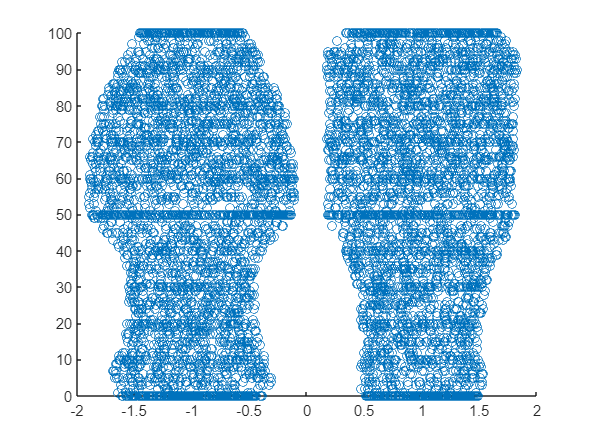


figure; hold on; 
swarmchart(master.highcue_indx, master.img_rate)

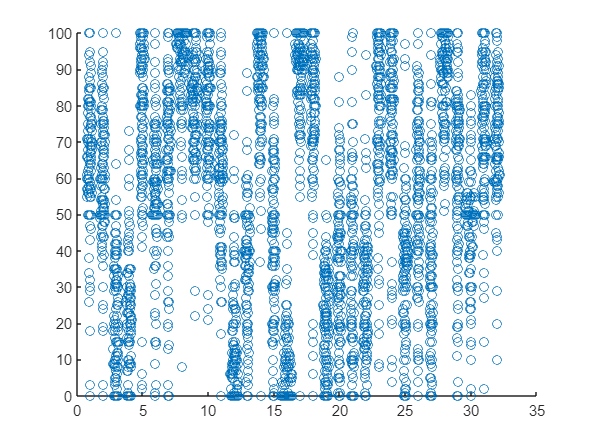


figure; hold on; 
swarmchart(master.Pair(master.highcue_indx == 1), master.img_rate(master.highcue_indx == 1))

hold off;

Let's start off with a very simple regression for predicting the valence score from the normative OASIS valence ratings.

We'll include a positive control for something that should have no relationship with the ratings for a sanity check.  

lme1 = fitlme(master, 'img_rate ~ Valence_mean')

lme1 = Linear mixed-effects model fit by ML

Model information:
    Number of observations            7872
    Fixed effects coefficients           2
    Random effects coefficients          0
    Covariance parameters                1

Formula:
    img_rate ~ 1 + Valence_mean

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    69206    69227    -34600           69200   

Fixed effects coefficients (95% CIs):
    Name                    Estimate    SE           tStat      DF      pValue        Lower      Upper  
    {'(Intercept)' }        -5.1575       0.58831    -8.7665    7870    2.2311e-18    -6.3107    -4.0042
    {'Valence_mean'}         1.0393     0.0097856     106.21    7870             0     1.0202     1.0585

Random effects covariance parameters (95% CIs):
Group: Error
    Name               Estimate    Lower     Upper 
    {'Res Std'}        19.617    

badlme = fitlme(master, 'img_rate ~ Half')

badlme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            7872
    Fixed effects coefficients           2
    Random effects coefficients          0
    Covariance parameters                1

Formula:
    img_rate ~ 1 + Half

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    76205    76226    -38099           76199   

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE         tStat      DF      pValue     Lower      Upper 
    {'(Intercept)'}         51.932      1.0906      47.62    7870          0     49.794     54.07
    {'Half'       }        0.54345     0.68973    0.78791    7870    0.43077    -0.8086    1.8955

Random effects covariance parameters (95% CIs):
Group: Error
    Name               Estimate    Lower     Upper 
    {'Res Std'}        30.598      30.124    31.079


 It looks like there's a strong connection between these subject valence ratings and the OASIS valence ratings. This is not surprising. 

What if we add in the variable of interest? 

lme2 = fitlme(master, 'img_rate ~ Valence_mean + highcue_indx')

lme2 = Linear mixed-effects model fit by ML

Model information:
    Number of observations            7872
    Fixed effects coefficients           3
    Random effects coefficients          0
    Covariance parameters                1

Formula:
    img_rate ~ 1 + highcue_indx + Valence_mean

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    69118    69146    -34555           69110   

Fixed effects coefficients (95% CIs):
    Name                    Estimate    SE         tStat      DF      pValue        Lower      Upper 
    {'(Intercept)' }        -5.1567     0.58497    -8.8154    7869      1.45e-18    -6.3034     -4.01
    {'highcue_indx'}         2.0889     0.21984     9.5018    7869    2.6831e-21      1.658    2.5199
    {'Valence_mean'}         1.0393     0.00973     106.82    7869             0     1.0203    1.0584

Random effects covariance parameters (95% CIs):

compare(lme1, lme2)

ans =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat    deltaDF    pValue
    lme1     3     69206    69227    -34600                               
    lme2     4     69118    69146    -34555    89.77     1          0     


This produces a significant improvement. That's good news. 

Can we improve by adding subjects as a random effect? 

lme3 = fitlme(master, 'img_rate ~ Valence_mean + highcue_indx + (1|subj)')

lme3 = Linear mixed-effects model fit by ML

Model information:
    Number of observations            7872
    Fixed effects coefficients           3
    Random effects coefficients        123
    Covariance parameters                2

Formula:
    img_rate ~ 1 + highcue_indx + Valence_mean + (1 | subj)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    68754    68789    -34372           68744   

Fixed effects coefficients (95% CIs):
    Name                    Estimate    SE          tStat      DF      pValue        Lower      Upper  
    {'(Intercept)' }        -5.1567      0.73432    -7.0224    7869    2.3619e-12    -6.5962    -3.7173
    {'highcue_indx'}         2.0889      0.21182     9.8615    7869    8.2852e-23     1.6737     2.5041
    {'Valence_mean'}         1.0393     0.009375     110.86    7869             0     1.0209     1.0577

Random effects covariance 

compare(lme2, lme3, 'CheckNesting', true)

ans =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat    deltaDF    pValue
    lme2     4     69118    69146    -34555                               
    lme3     5     68754    68789    -34372    365.94    1          0     


This was also a significant improvement. 

What about trying to account for individual preference? We could use image number, but that might really limit our degrees of freedom... Let's start with image pair and see what happens

lme4 = fitlme(master, 'img_rate ~ Valence_mean + highcue_indx + (Pair|subj)')

lme4 = Linear mixed-effects model fit by ML

Model information:
    Number of observations            7872
    Fixed effects coefficients           3
    Random effects coefficients        246
    Covariance parameters                4

Formula:
    img_rate ~ 1 + highcue_indx + Valence_mean + (1 + Pair | subj)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    68755    68804    -34371           68741   

Fixed effects coefficients (95% CIs):
    Name                    Estimate    SE           tStat      DF      pValue        Lower      Upper  
    {'(Intercept)' }        -5.4453       0.72903    -7.4693    7869    8.9307e-14    -6.8744    -4.0162
    {'highcue_indx'}         2.0889       0.21176     9.8643    7869    8.0571e-23     1.6738      2.504
    {'Valence_mean'}         1.0393     0.0093723     110.89    7869             0     1.0209     1.0577

Random effects 

compare(lme3, lme4, 'CheckNesting', true) %Not significant

ans =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat    deltaDF    pValue 
    lme3     5     68754    68789    -34372                                
    lme4     7     68755    68804    -34371    3.399     2          0.18277



lme5 = fitlme(master, 'img_rate ~ Valence_mean + highcue_indx + (Image|subj)')

lme5 = Linear mixed-effects model fit by ML

Model information:
    Number of observations            7872
    Fixed effects coefficients           3
    Random effects coefficients        246
    Covariance parameters                4

Formula:
    img_rate ~ 1 + highcue_indx + Valence_mean + (1 + Image | subj)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    68748    68797    -34367           68734   

Fixed effects coefficients (95% CIs):
    Name                    Estimate    SE           tStat      DF      pValue        Lower      Upper  
    {'(Intercept)' }        -5.6708       0.72099    -7.8653    7869    4.1704e-15    -7.0841    -4.2575
    {'highcue_indx'}         2.0892       0.21151     9.8777    7869    7.0647e-23     1.6746     2.5039
    {'Valence_mean'}         1.0393     0.0093612     111.02    7869             0      1.021     1.0577

Random effects

compare(lme3, lme5, 'CheckNesting', true) %Significant

ans =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat    deltaDF    pValue   
    lme3     5     68754    68789    -34372                                  
    lme5     7     68748    68797    -34367    10.647    2          0.0048756


The `image pair x subj` interaction was not a significant improvement, but `image number x subject` was. That's a bit disappointing, and makes me wonder if the image pairs will actually be that helpful for comparisons. 

What does this look like right now?

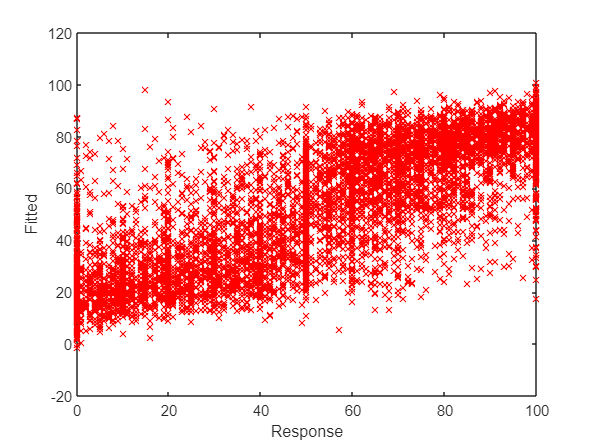

F = fitted(lme5);
R = response(lme5);
figure();
plot(R,F,'rx')
xlabel('Response')
ylabel('Fitted')

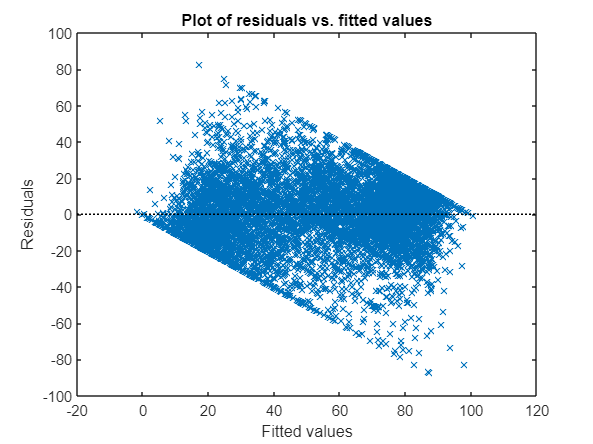


figure();
plotResiduals(lme5, 'fitted')